# 3-D  Trajectory planning with a straight-line path in Cartesian space for the position of the origin of the end-effector and a straight-line path in SO(3) for the orientation of the end-effector and a 3rd-order polynomials for time scaling

## Construct The Robot

clc; clear;

robot = importrobot('Franka_Emika_Panda.urdf');

robot.DataFormat = 'column';

Show details of the robot to validate the input properties. The robot should have two non-fixed joints, where the link bodies are connected to their parent bodies via a revolute joint, and the end effector is connected to its parent body via a fixed joint.

showdetails(robot)

--------------------
Robot: (9 bodies)

 Idx      Body Name     Joint Name     Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------     ----------     ----------      ----------------   ----------------
   1          link1         joint1       revolute              link0(0)   link2(2)  
   2          link2         joint2       revolute              link1(1)   link3(3)  
   3          link3         joint3       revolute              link2(2)   link4(4)  
   4          link4         joint4       revolute              link3(3)   link5(5)  
   5          link5         joint5       revolute              link4(4)   link6(6)  
   6          link6         joint6       revolute              link5(5)   link7(7)  
   7          link7         joint7       revolute              link6(6)   b_frame(8)  
   8        b_frame        b_frame          fixed              link7(7)   
   9        s_frame        s_frame          fixed              link0(0)   
--------------------


robot.homeConfiguration

ans =          0
         0
         0
   -1.5708
         0
         0
         0


panda_model()
M

M =     1.0000         0         0    0.0880
         0   -1.0000         0         0
         0         0   -1.0000    0.9260
         0         0         0    1.0000


B

B =          0         0         0         0         0         0         0
         0   -1.0000         0    1.0000         0    1.0000         0
   -1.0000         0   -1.0000         0   -1.0000         0    1.0000
         0    0.5930         0   -0.2770         0    0.1070         0
   -0.0880         0   -0.0880         0   -0.0880         0         0
         0    0.0880         0   -0.0055         0   -0.0880         0


S

S =          0         0         0         0         0         0         0
         0    1.0000         0   -1.0000         0   -1.0000         0
    1.0000         0    1.0000         0    1.0000         0   -1.0000
         0   -0.3330         0    0.6490         0    1.0330         0
         0         0         0         0         0         0    0.0880
         0         0         0   -0.0825         0         0         0


## Define The Trajectory

#### **Control random number generator**

rng default

### **Choose two arbitrary and feasible desired configurations**

**Start Configuration**

First, an arbitrary and feasible configuration has been chosen for start configuration. 

X_start = [0 0 -1 0.36; 0 -1 0 0; -1 0 0 0.64; 0 0 0 1];
vpa(X_start)

$$ans = \left(\begin{array}{cccc} 0 & 0 & -1.0 & 0.36\\ 0 & -1.0 & 0 & 0\\ -1.0 & 0 & 0 & 0.64\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

Now, using Inverse Kinematic, the corresponding joint angles can be obtained.

q_start = IK_SpaceForm(X_start, [0; 0; 0; -pi/2; 0; 0; 0], [1e-3, 1e-3], S, M);
vpa(q_start', 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & -1.571 & 0 & 0 & 0 \end{array}\right)$$

To check the obtained joint angles, Forward Kinematc can be employed.

X_start = round(FK_SpaceForm(S, M, q_start), 4);
start_config = vpa(X_start)

$$start\_config = \left(\begin{array}{cccc} 0 & 0 & -1.0 & 0.3595\\ 0 & -1.0 & 0 & 0\\ -1.0 & 0 & 0 & 0.6435\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

**End Configuartion**

Now, an arbitrary configuration has been chosen for end configuration. For the sake of convenience we can choose an arbitrary joint angles to obtain T.

robot_finalconfig = [2.0457; 0.4303; -0.8637; -1.5310; -0.5690; 0.2689; -1.5071];
X_end = FK_SpaceForm(S, M, robot_finalconfig);
vpa(X_end, 4)

$$ans = \left(\begin{array}{cccc} -0.5932 & 0.7773 & -0.2097 & 0.1516\\ 0.07337 & -0.2072 & -0.9755 & 0.4353\\ -0.8017 & -0.5941 & 0.06592 & 0.5339\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

Using Inverse Kinematic, the corresponding joint angles can be obtained.

As the Inverse Kinematic is dependent on initial guess, it is better to obtain the end configuration using FK.

q_end = IK_SpaceForm(X_end, [2.8; 0; -1.2; -1.5; -0.5; 0.3; -1.5], [1e-10, 1e-10], S, M);
vpa(q_end', 4)

$$ans = \left(\begin{array}{ccccccc} 2.337 & 0.7016 & -1.319 & -1.601 & -0.6329 & 0.4319 & -1.907 \end{array}\right)$$

So, the end configuration can be obtained. It has the same position and slightly different orientation.

X_end = FK_SpaceForm(S, M, q_end);
end_config = vpa(X_end, 4)

$$end\_config = \left(\begin{array}{cccc} -0.5936 & 0.7771 & -0.2094 & 0.1515\\ 0.07342 & -0.2068 & -0.9756 & 0.4353\\ -0.8014 & -0.5945 & 0.06568 & 0.534\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

**Start and End Configuration**

Now, start and end configuration cen be visualized.

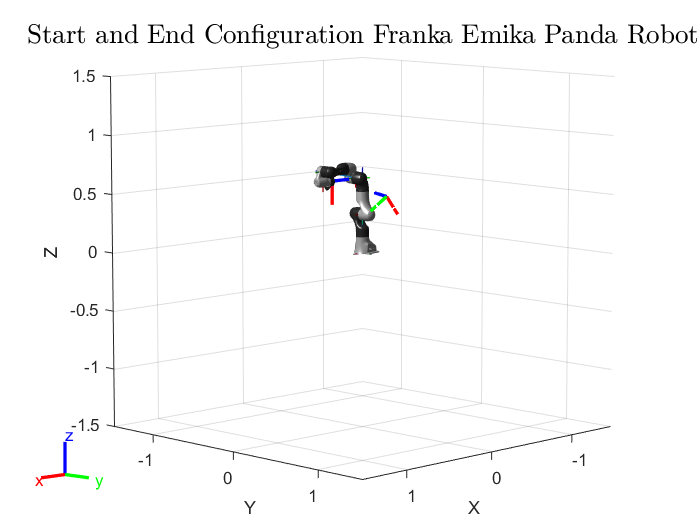

clf;
show(robot,q_start ,'Visuals','on');
hold on;
str = "Start and End Configuration Franka Emika Panda Robot";
title(str, FontSize=16, Interpreter="latex");

triad('Matrix',X_start,'Scale',0.2,'LineWidth',2 ,'linestyle','-');
triad('Matrix',X_end, 'Scale',0.2,'LineWidth',2 ,'linestyle','-.');

## Point-to-Point straight-line path in Cartesian space for the position of the origin of the end-effector and a straight-line path in SO(3) for the orientation of the end-effector and a 3rd-order polynomials for time scaling

The velocity profile has four parameters:

- **End Time **— Duration of each segment between two waypoints

- **Peak Velocity **— Peak velocity for a each segment

- **Acceleration Time** — Time spent in the acceleration and deceleration phases of each segment

- **Peak Acceleration **— Magnitude of the acceleration applied during the acceleration and deceleration phases of each segment

peakVelocities = [150, 150, 150, 150, 180, 180, 180]'.*pi/180;
vpa(peakVelocities', 5)

$$ans = \left(\begin{array}{ccccccc} 2.618 & 2.618 & 2.618 & 2.618 & 3.1416 & 3.1416 & 3.1416 \end{array}\right)$$

peakAcceleration = [850, 425, 570, 700, 850, 1140, 1140]'.*pi/180;
vpa(peakAcceleration', 5)

$$ans = \left(\begin{array}{ccccccc} 14.835 & 7.4176 & 9.9484 & 12.217 & 14.835 & 19.897 & 19.897 \end{array}\right)$$

Plot the robot for each frame of the solution using that specific robot configuration. Also, plot the desired trajectory.

Show the robot in the first configuration of the trajectory. Plot the desired trajectory.

## Third-order Polynomials for time scaling

A convenient form for the time scaling s(t) is a cubic polynomial of time.

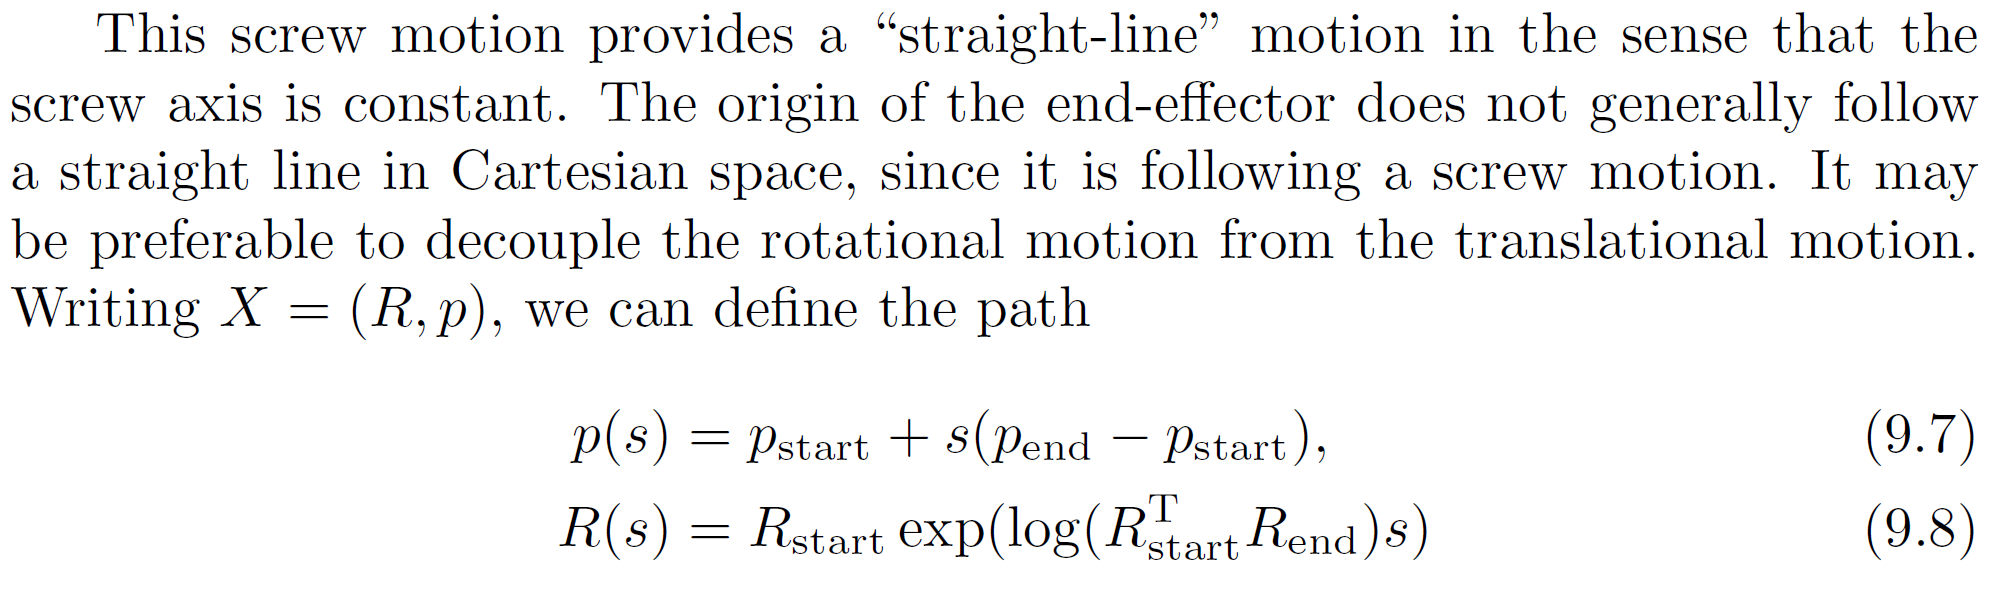

**Final time can be obtained numerically**

- **Assume T as final time**

- **Find X_start and X_end**

- **Find joint angles by IK**

- **Find max joint velocity and aceeleration and compare to the limits**

- **Correct T**

**Minimum T for this task is 0.65s due to acceleration limit for Joint 2.**

t0 = 0; %Start Time
sampleRate = 20; % Sample Rate
tf = 0.65 %Final Time

tf = 0.6500

t = linspace(t0, tf, sampleRate); % Time
tstp = sampleRate;
dt = (tf-t0)/tstp

dt = 0.0325

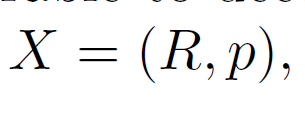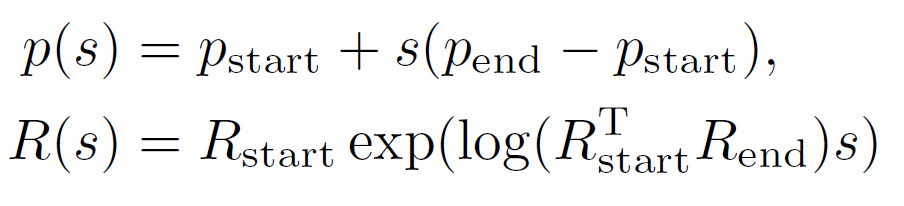

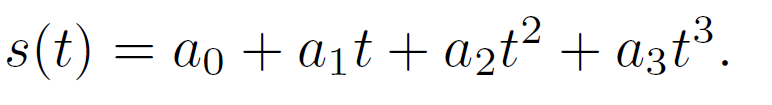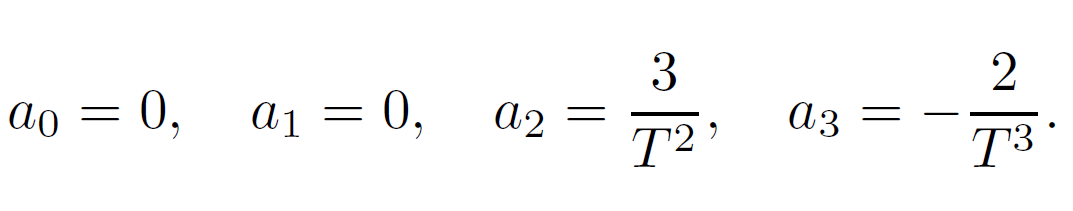

traj = CartesianTrajectory(X_start, X_end, tf, tstp, 3);


q = zeros(tstp, numcols(q_start'))';
qd = zeros(tstp, numcols(q_start'))';
qdd = zeros(tstp, numcols(q_start'))';


theta0 = q_start;
for i = 1:tstp
    q(:,i) = IK_BodyForm(traj{i}, theta0, [1e-10, 1e-10], B, M);
    theta0 = q(:,i);
end

qd  = diff(q, 1, 2)./dt;
qd = smoothdata(qd,"movmean","SmoothingFactor",0.5);
qdd = diff(qd, 1, 2)./dt;
qdd = smoothdata(qdd,"movmean","SmoothingFactor",0.5);

### Initial guess for minimum T

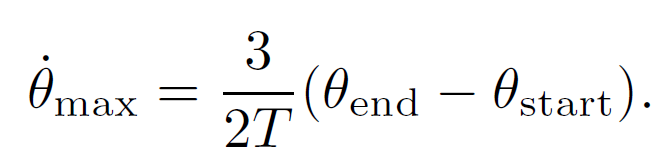

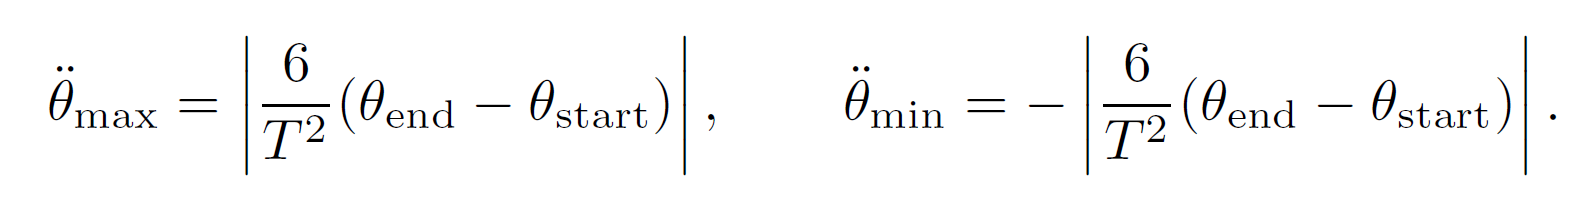

q0 = q(:, 1);
q1 = q(:, tstp);

Tf_v = 3/2 .* abs(q1 - q0)./peakVelocities;
Tf_a = sqrt(2.*abs(q1-q0)./peakAcceleration);

minT = max(max(Tf_v, Tf_a))

minT = 0.4147

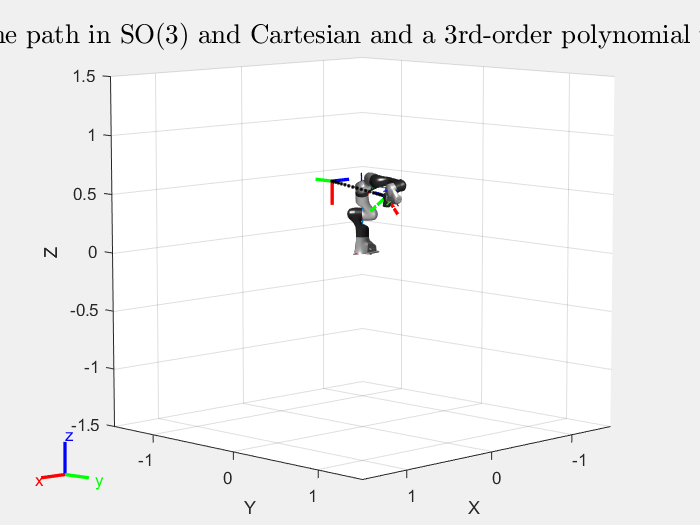


clf; figure;
set(gcf,"Visible","on");
rc = rateControl(sampleRate);
show(robot,q_start ,'Visuals','on');
hold on;

triad('Matrix',X_start,'Scale',0.2,'LineWidth',2 ,'linestyle','-');
triad('Matrix',X_end, 'Scale',0.2,'LineWidth',2 ,'linestyle','-.');
str = "Smooth trajectory with a straight-line path in SO(3) and Cartesian and a 3rd-order polynomial with minimum motion time T = " + num2str(tf) + " s";
title(str, FontSize=16, Interpreter="latex");

for i = 1:tstp
    show(robot,q(:,i),FastUpdate=true, PreservePlot=false);
    drawnow;
    hold on;

    T = FK_BodyForm(B, M, q(:,i));
    X = T(1, 4);
    Y = T(2, 4);
    Z = T(3, 4);
    plot3(X, Y, Z, 'black.');
    waitfor(rc);
end

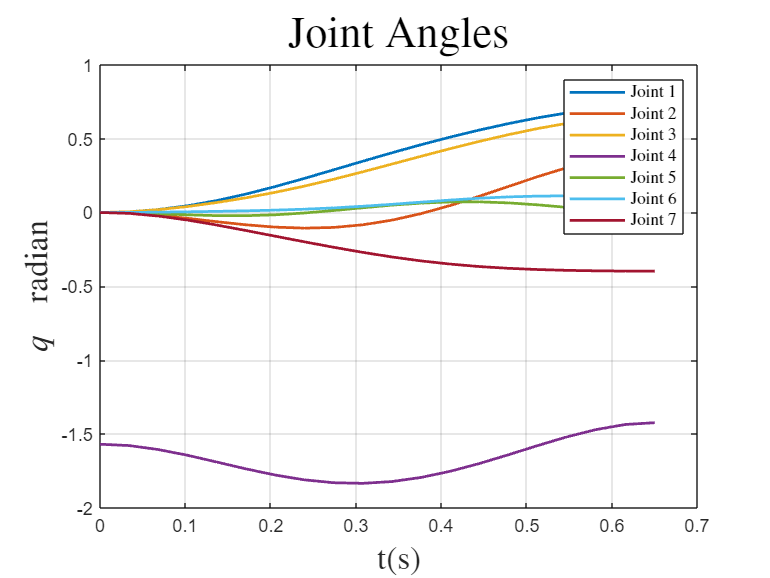

figure;

plot(t,q, LineWidth=1.5)
title('Joint Angles', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

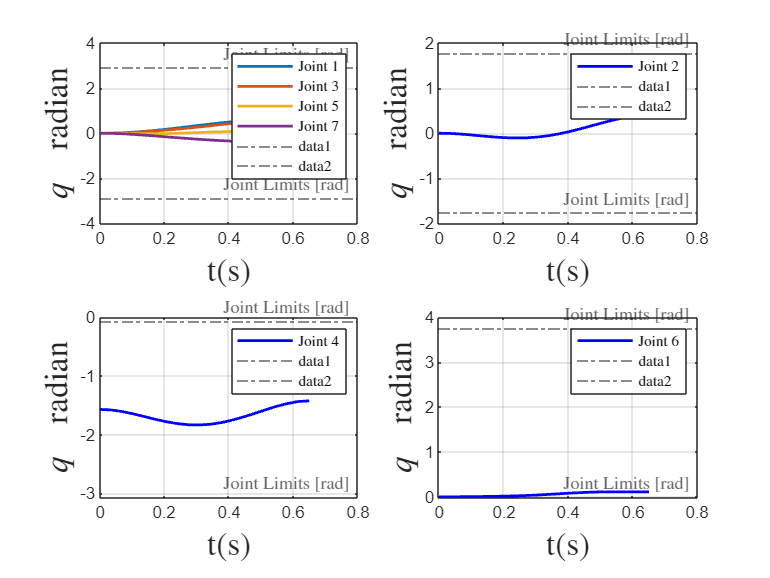

clf; figure;
title('Joint Angles', Interpreter='latex', FontSize=24);

subplot(2, 2, 1);
plot(t,q(1, :), LineWidth=1.5)
hold on;
plot(t,q(3, :), LineWidth=1.5)
hold on;
plot(t,q(5, :), LineWidth=1.5)
hold on;
plot(t,q(7, :), LineWidth=1.5)

legend('Joint 1','Joint 3','Joint 5','Joint 7', 'Interpreter', 'latex');
yline(panda.qlim(1, :),'-.','Joint Limits [rad]', Interpreter='latex');

ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;


subplot(2, 2, 2);
plot(t,q(2, :), LineWidth=1.5, Color='b')
legend('Joint 2', 'Interpreter', 'latex');
yline(panda.qlim(2, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 3);
plot(t,q(4, :), LineWidth=1.5, Color='b')
legend('Joint 4', 'Interpreter', 'latex');
yline(panda.qlim(4, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

subplot(2, 2, 4);
plot(t,q(6, :), LineWidth=1.5, Color='b')
legend('Joint 6', 'Interpreter', 'latex');
yline(panda.qlim(6, :),'-.','Joint Limits [rad]', Interpreter='latex');
ylabel('$q \quad \textrm{radian}$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

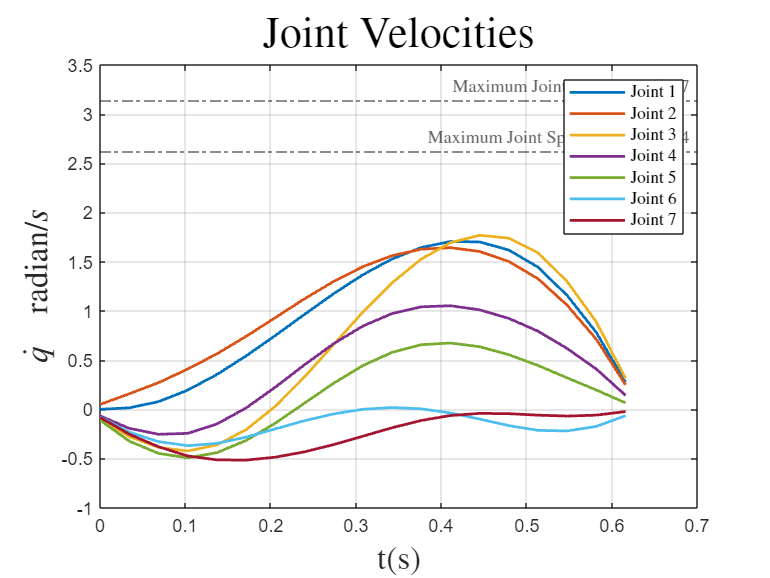



figure;
td = t(1: tstp-1);
plot(td,qd, LineWidth=1.5)



yline(peakVelocities(1),'-.','Maximum Joint Speed, J1, J2, J3, J4', Interpreter='latex');
yline(peakVelocities(5),'-.','Maximum Joint Speed, J5, J6, J7', Interpreter='latex');



title('Joint Velocities', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel("$\dot{q} \quad {\textrm{radian}}/{s}$", Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);
grid on;

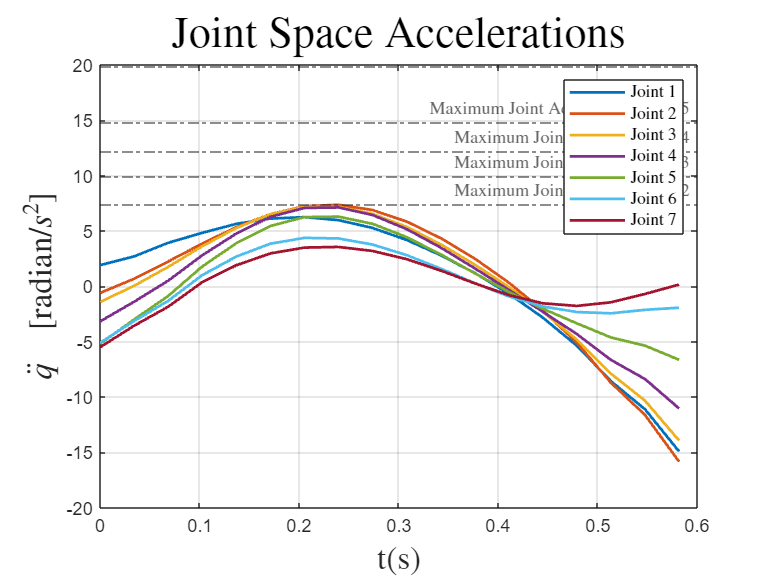


figure;
tdd = t(1:tstp-2);

plot(tdd,qdd, LineWidth=1.5)

hold on;

yline(peakAcceleration(1),'-.','Maximum Joint Acceleration, J1, J5', Interpreter='latex');
yline(peakAcceleration(2),'-.','Maximum Joint Acceleration, J2', Interpreter='latex');
yline(peakAcceleration(3),'-.','Maximum Joint Acceleration, J3', Interpreter='latex');
yline(peakAcceleration(4),'-.','Maximum Joint Acceleration, J4', Interpreter='latex');
yline(peakAcceleration(6),'-.','Maximum Joint Acceleration, J6, J7', Interpreter='latex');

title('Joint Space Accelerations', Interpreter='latex', FontSize=24);
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6','Joint 7', 'Interpreter', 'latex');
ylabel('$\ddot{q} \quad \left[ \textrm{radian}/ s^2 \right]$', Interpreter='latex', FontSize=18);
xlabel('t(s)', Interpreter='latex', FontSize=18);

grid on;